# Simple Longitudinal Vehicle Component

Copyright 2020-2021 The Mathworks, Inc.

## Open model

mdl = "Vehicle1DBasic_test_harness";
if not(bdIsLoaded(mdl))
  % A callback function in the model runs the setup script.
  open_system(mdl)
else
  Vehicle1DBasic_setup
end

## Load Input Signals

Input signals are defined as timetable object in a separate MATLAB function. This script only loads it to the workspace.

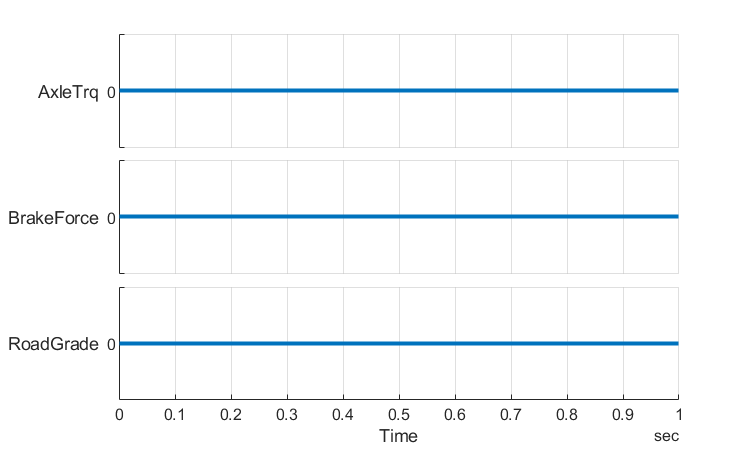

fig = figure;
[inputSignals_Vehicle1D, inputBus_Vehicle1D, t_end] = ...
  Vehicle1DBasic_inputs( "PlotParent",fig, "InputPattern","coastdown" );

## Run Simulation

Set test-specific parameters and run simulation.

% Set initial conditions
initial.vehicleSpeed_kph = 0;
initial.GeartrainSpeed_rpm = 0;

% Override block parameters

% Set Simulation Input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Visualize Simulation Result

Inpus

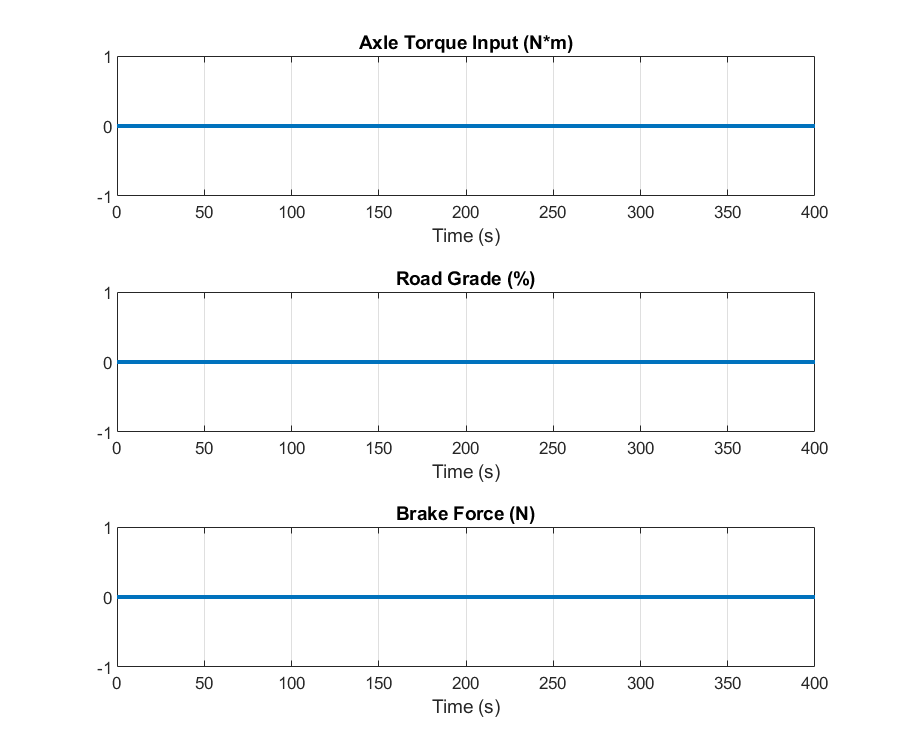

fig = figure;
Vehicle1DBasic_plot_result_inputs( "Dataset",out.logsout, "PlotParent",fig );

Outputs

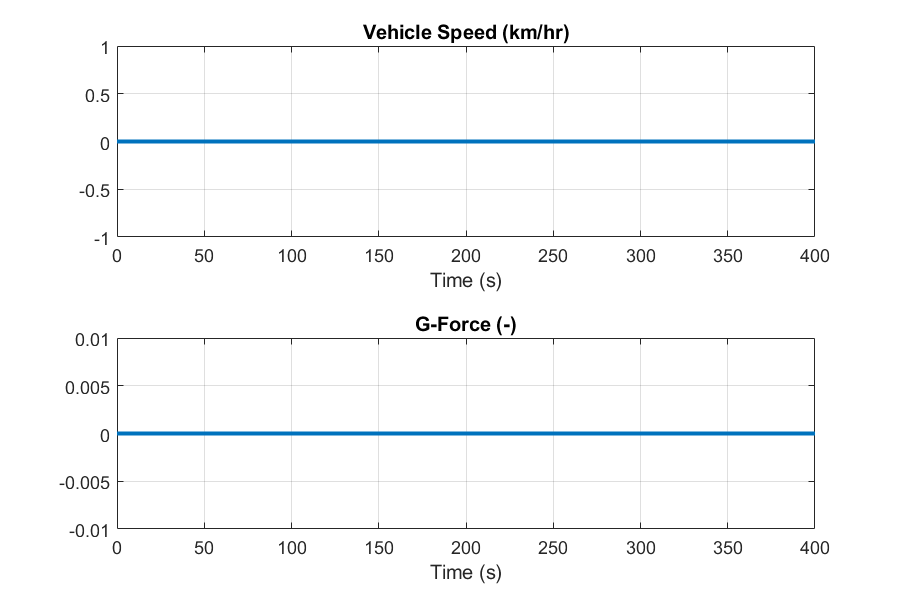

fig = figure;
Vehicle1DBasic_plot_result_outputs( "Dataset",out.logsout, "PlotParent",fig );